clc; close all ; clearvars;

## Parameters for generate the data set

d=3; %dimensionality
c=3; % quantity classes

m1=[-0.5622721686261278 1.1704601236336887 -0.6081879550075613]'; %means vectors
m2=[0.6904692449166845 0.08872418498635462 -0.7791934299030396]';
m3=[0.19756948018729084 -0.36619207554951666 0.1686225953622233]';
m=[m1 m2 m3];

S1=[0.035372  0.001631  0.061266; 0.001631  0.382650 -0.058443; 0.061266 -0.058443  0.509344]; %covariance matrices 
S2=[0.107327  0.059705  0.190813; 0.059705  0.171434 -0.002145; 0.190813 -0.002145  1.046333];
S3=[0.800716 -0.529648  0.404252; -0.529648  1.363328 -0.658907; 0.404252 -0.658907  1.260925];
S(:,:,1)=S1;S(:,:,2)=S2;S(:,:,3)=S3;

% A priori probabilities
P1=1/3;  P2=1/3; P3=1/3 ;
P=[P1 P2 P3]';

## Generate data set training: Xtrain (aprendizaje)

N=300;
N1=fix(N*P1); N2=fix(N*P2); N3=fix( N*P3);
% randn('seed',0);
% [Xtrain,ytrain]=generate_gauss_classes(m,S,P,N);
Xtrain = csvread('../Dataset/Train_InputT.csv');
ytrain = csvread('../Dataset/Train_TargetsT.csv');

## Generate data set test: Xtest (prueba)

% randn('seed',100);
Nt=150; 
Nt1=fix(Nt*P1); Nt2=fix(Nt*P2); Nt3=fix( Nt*P3);
Xtest = csvread('../Dataset/Test_InputT.csv');
ytest = csvread('../Dataset/Test_TargetsT.csv');
% [Xtest,ytest]=generate_gauss_classes(m,S,P,Nt);

## Display Xtrain (Entrenamiento)

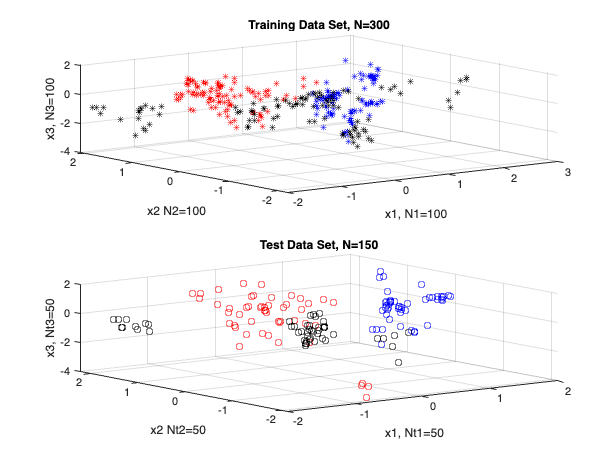

subplot(2,1,1); plot3(Xtrain(1,1:N1),Xtrain(2,1:N1),Xtrain(3,1:N1),'*r',Xtrain(1,N1+1:N1+N2),...
    Xtrain(2,N1+1:N1+N2),Xtrain(3,N1+1:N1+N2),'*b', Xtrain(1,N1+N2+1:N1+N2+N3),...
    Xtrain(2,N1+N2+1:N1+N2+N3),Xtrain(3,N1+N2+1:N1+N2+N3),'*k'); 
grid on; title(['Training Data Set, N=' num2str(N)]); 
xlabel(['x1, N1=' num2str(N1)] );ylabel(['x2 N2=' num2str(N2)]);zlabel(['x3, N3=' num2str(N3)]);
% Display Xtest (Prueba)
subplot(2,1,2); plot3(Xtest(1,1:Nt1),Xtest(2,1:Nt1),Xtest(3,1:Nt1),'or',Xtest(1,Nt1+1:Nt1+Nt2),...
    Xtest(2,Nt1+1:Nt1+Nt2),Xtest(3,Nt1+1:Nt1+Nt2),'ob', Xtest(1,Nt1+Nt2+1:Nt1+Nt2+Nt3),...
    Xtest(2,Nt1+Nt2+1:Nt1+Nt2+Nt3),Xtest(3,Nt1+Nt2+1:Nt1+Nt2+Nt3),'ok'); 
grid on; title(['Test Data Set, N=' num2str(Nt)]); 
xlabel(['x1, Nt1=' num2str(Nt1)] );ylabel(['x2 Nt2=' num2str(Nt2)]);zlabel(['x3, Nt3=' num2str(Nt3)]);

## 1. Compute the kNN estimates of the pdfs p^(x|wi)

knn=5;
%knn=15;
px_c1=estimar_kNN_density(Xtest,Xtrain(:,1:N1), knn); % p(x|w1)
px_c2=estimar_kNN_density(Xtest,Xtrain(:,N1+1:N1+N2), knn); % p(x|w2)
px_c3=estimar_kNN_density(Xtest,Xtrain(:,N1+N2+1+1:N1+N2+N3), knn); % p(x|w3)

## 2. Bayesian classifier, using the kNN pdf estimates, in order to

classify the data vectors of Xp. Assign x to wi if p(x|wi)P(wi) > p(x|wj) P(wj)

A_Prob_Xp= [P1*px_c1; P2*px_c2; P3*px_c3;]; % A Posteriori Probability
[MAX, AssigClass]=max(A_Prob_Xp); %

## 3. Compute the classification error for each classifier

Index set for plotconfusion Labe Tests Data Set 

ind_t1=find(ytest==1);ind_t2=find(ytest==2); ind_t3=find(ytest==3);
Targets=zeros(c,Nt);
Targets(1,ind_t1)=1; Targets(2,ind_t2)=1; Targets(3,ind_t3)=1;

## Label Bayes Classifier with kNN pdf estimates

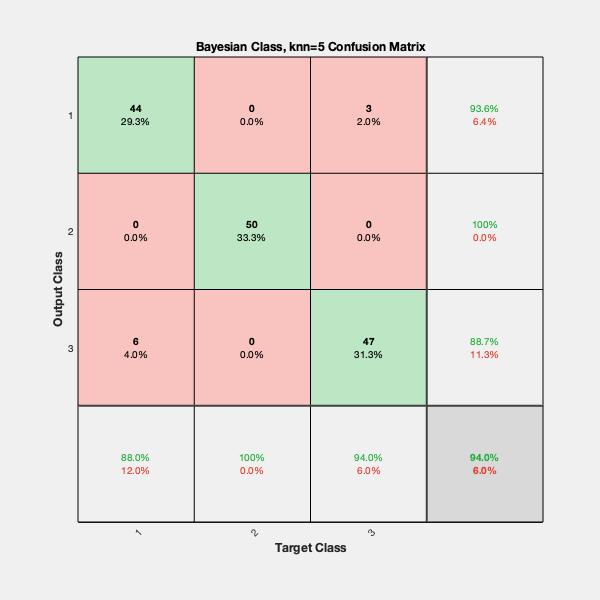

ind_b1=find(AssigClass==1); ind_b2=find(AssigClass==2); ind_b3=find(AssigClass==3);
OutputsB=zeros(c,Nt);
OutputsB(1,ind_b1)=1; OutputsB(2,ind_b2)=1; OutputsB(3,ind_b3)=1;
% Plot Confusion
figure; plotconfusion(Targets,OutputsB,['Bayesian Class, knn=' num2str(knn)  ]);